#### Building proximity graphs

Clear workspace, general setup

clear; close all
% cd C:\Users\enrew\Downloads\
% addpath("ProximityGraphs\")

From the manual page:

  [CBSG]=CircleBetaSkeletonGraph(data,dist,beta)

  data: NxD N point in D-dimension real space

  dist: NxN Euclidean distance matrix between each pair of point dist(i,k)=norm(data(i,:)-data(k,:)||

  beta: [-1,1] parameter to tune the size of the neighborhood

                 empty graph    : beta=-1;

                 Gabriel graph  : beta=0; 

                 complete graph : beta=1;  

                 beta_i<beta_k => CBSG_i \subset CBSG_k

                 CBSG is an UNDIRECTED graph

  OUTPUT:

  CBSG: N cells CBSG{i}=[a b...f] set of index in data rows of the CBSG neighbors of i

Prepare some data - firstly randomly position some nodes in a square

L=10; % side of square
numNode = 200;
nodeCoordinates = L*rand(numNode,2);

I am going to sort the nodes so they ordered from bottom left to top right

[~,inds]=sort(sum(nodeCoordinates')');
nodeCoordinates=nodeCoordinates(inds,:);

Then compute the required distance matrix:

distanceMatrix = squareform(pdist(nodeCoordinates));

Attempt the call..

beta=1.5; % documentation says this is the Gabriel graph - caution with defn of beta
cbsg = CircleBetaSkeletonGraph(nodeCoordinates,distanceMatrix,beta);

But the data format is screwed up - so they provide a function to convert to an adjacency matrix:

A=cell2mat(cbsg);

Notice this is giving you a symmetric adjacency matrix (ie all streets two-way)

sum(sum(A-A'))

Arrays have incompatible sizes for this operation.

Related documentation

Let's have a look at the distribution of the node degree:

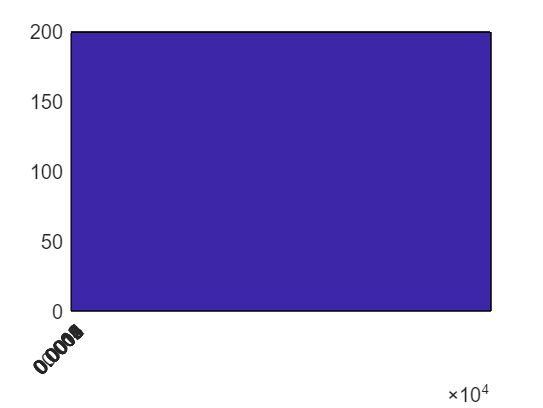

hist(sum(A),[1:15])

We could try to get this thing into Matlab's toolbox - which actually takes an adjacency matrix as one way of setting up a graph. But if you want to set up weights, you give it a matrix of weights instead of the adjency matrix.

G = graph(A.*distanceMatrix,cellstr(num2str([1:numNode]')));

Arrays have incompatible sizes for this operation.

Related documentation

% the second bit is just naming the nodes 1,2,3 etc.

Plotting? NB at the moment - there is no coordinate information in G.

plot(G);

Unrecognized function or variable 'G'.

But it is easy to get it in:

plot(G,'XData',nodeCoordinates(:,1),'YData',nodeCoordinates(:,2),'NodeLabelMode','auto')

Unrecognized function or variable 'G'.

axis([0 L 0 L])
axis equal